load = [0:50:800]./60;
load(1) = 1/60;
response_time = zeros;
throughput = zeros;
matfiles = dir(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity misto\summary reports', '*.csv'));
for i = 1 : length(matfiles)
    fileID = fopen(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity misto\summary reports', matfiles(i).name));
    C = textscan(fileID,'%q %q %q %q %q %q %q %q %q %q %q %q %q','Delimiter',',');
    response_time(i) = str2double(C{3}{8});
    throughput(i) = str2double(strrep(C{8}{8},',','.'));
    fclose(fileID);
end
subplot(2,1,1);
plot(load, response_time.*.001)
xlabel('Number of request (req/s)')
ylabel('Response time (s)')
line([200 200]./60, [0 21000].*0.001,'Color','green');
line([350 350]./60, [0 21000].*0.001,'Color','red');
legend('andamento','knee capacity','usable capacity')
subplot(2,1,2);
plot(load, throughput)
xlabel('Number of request (req/s)')
ylabel('Throughput (req/sec)')
line([200 200]./60, [0 6],'Color','green');
line([350 350]./60, [0 6],'Color','red');
legend('andamento','knee capacity','usable capacity')
%saveas(gcf,'capacity_misto','png');
clf
clear

load = [0:50:800]./60;
load(1) = 1/60;
response_time = zeros;
throughput = zeros;
matfiles = dir(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity big\summary reports', '*.csv'));
for i = 1 : length(matfiles)
    fileID = fopen(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity big\summary reports', matfiles(i).name));
    C = textscan(fileID,'%q %q %q %q %q %q %q %q %q %q %q %q %q','Delimiter',',');
    response_time(i) = str2double(C{3}{4});
    throughput(i) = str2double(strrep(C{8}{4},',','.'));
    fclose(fileID);
end
subplot(2,1,1);
plot(load, response_time.*.001)
xlabel('Number of request (req/s)')
ylabel('Response time (s)')
%line([200 200]./60, [0 21000].*0.001,'Color','green');
%line([350 350]./60, [0 21000].*0.001,'Color','red');
%legend('andamento','knee capacity','usable capacity')
subplot(2,1,2);
plot(load, throughput)
xlabel('Number of request (req/s)')
ylabel('Throughput (req/sec)')
%line([200 200]./60, [0 6],'Color','green');
%line([350 350]./60, [0 6],'Color','red');
%legend('andamento','knee capacity','usable capacity')
%saveas(gcf,'capacity_big','png');
clf
clear

load = [0:50:650]./60;
load(1) = 1/60;
response_time = zeros;
throughput = zeros;
matfiles = dir(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity medium\summary reports', '*.csv'));
for i = 1 : length(matfiles)
    fileID = fopen(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity medium\summary reports', matfiles(i).name));
    C = textscan(fileID,'%q %q %q %q %q %q %q %q %q %q %q %q %q','Delimiter',',');
    response_time(i) = str2double(C{3}{4});
    throughput(i) = str2double(strrep(C{8}{4},',','.'));
    fclose(fileID);
end
subplot(2,1,1);
plot(load, response_time.*.001)
xlabel('Number of request (req/s)')
ylabel('Response time (s)')
%line([200 200]./60, [0 21000].*0.001,'Color','green');
%line([350 350]./60, [0 21000].*0.001,'Color','red');
%legend('andamento','knee capacity','usable capacity')
subplot(2,1,2);
plot(load, throughput)
xlabel('Number of request (req/s)')
ylabel('Throughput (req/sec)')
%line([200 200]./60, [0 6],'Color','green');
%line([350 350]./60, [0 6],'Color','red');
%legend('andamento','knee capacity','usable capacity')
%saveas(gcf,'capacity_big','png');
clf
clear

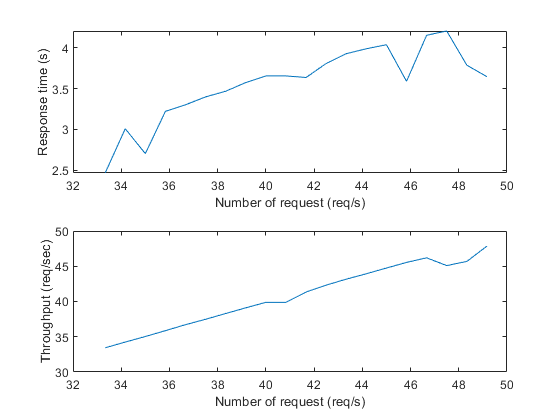

load = [2000:50:2950]./60;
response_time = zeros;
throughput = zeros;
matfiles = dir(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity small\summary reports', '*.csv'));
for i = 1 : length(matfiles)
    fileID = fopen(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity small\summary reports', matfiles(i).name));
    C = textscan(fileID,'%q %q %q %q %q %q %q %q %q %q %q %q %q','Delimiter',',');
    response_time(i) = str2double(C{3}{4});
    throughput(i) = str2double(strrep(C{8}{4},',','.'));
    fclose(fileID);
end
subplot(2,1,1);
plot(load, response_time.*.001)
xlabel('Number of request (req/s)')
ylabel('Response time (s)')
%line([200 200]./60, [0 21000].*0.001,'Color','green');
%line([350 350]./60, [0 21000].*0.001,'Color','red');
%legend('andamento','knee capacity','usable capacity')
subplot(2,1,2);
plot(load, throughput)
xlabel('Number of request (req/s)')
ylabel('Throughput (req/sec)')

%line([200 200]./60, [0 6],'Color','green');
%line([350 350]./60, [0 6],'Color','red');
%legend('andamento','knee capacity','usable capacity')
%saveas(gcf,'capacity_big','png');
clf
%clear